## Equation electriques du PMSM


$$\frac{d}{dt} i_{abc} = -r/L i_{abc} +p \psi_f /L e_{abc}(\theta) \omega_{meca} + u_{abc}$$



$$\frac{d}{dt} \omega__{meca} = p \psi_f/J e_{abc}(\theta)^T i_{abc} -B/J \omega_{meca} +T_m$$



$$e_a=\cos(p \theta_{meca})$$
 


$$e_b = e_a(t-T/3)$$


bemfm_a=-ScalarPhasorArray([0 1/2/1i],'z_pospart',true); %basic motiv of back emf, un per unit
bemfm_abc=bemfm_a.PhaseShift([0;-2*pi/3;2*pi/3]);
figure(1)
plot(bemfm_abc,title='back emf')


parametre de la machine

model.r=0.082; %Ohm
model.L=1.5e-3; %H
model.J=0.01650; %kg m²
model.p=4; %pole pair
model.psi_f=0.176; %Wb
model.Bf=0.02; %frottement

model.v_in=600;

bemf_abc=bemfm_abc*model.psi_f*model.p;

construction de la matrice

A=[-model.r/model.L*eye(3)    ,-1/model.L*bemf_abc;
    1/model.J*bemf_abc'       ,-model.Bf/model.J];


figure(2)
plot(A,1,0:0.01:2,title='A(t)')
C3=(eye(3)-ones((3))/3)

C3 =     0.6667   -0.3333   -0.3333
   -0.3333    0.6667   -0.3333
   -0.3333   -0.3333    0.6667



B=([model.v_in*eye(3)/model.L;zeros(1,3)]);
B=PhasorArray(B);

model.A=A;
model.B=B;
model.state_name={'i_{a}','i_{b}','i_{c}','\omega_{m}'};


COS = ScalarPhasorArray([0 1/2],'z_pospart', true)

COS = 1x1x3 PhasorArray of double representing a 1x1 real-valued periodic matrix with 1 harmonics

COS3 = COS.PhaseShift([0 -(2*pi/3) (2*pi/3)]);
SIN3 = COS3.PhaseShift(-pi/2);
Abc2Dq0 = (sqrt(2/3))*[COS3;-SIN3;(sqrt(2)/2*ones(1,3))]

Abc2Dq0 = 3x3x3 PhasorArray of double representing a 3x3 real-valued periodic matrix with 1 harmonics


figure
plot(Abc2Dq0,2*pi)

figure
plot(Abc2Dq0*Abc2Dq0.',2*pi)
ytickformat('%f')

value(reduce((Abc2Dq0)*bemf_abc))

ans = ans(:,:,1) =

   1.0e-15 *

   0.0000 + 0.1110i
   0.1110 + 0.0000i
   0.0000 + 0.0000i


ans(:,:,2) =

   1.0e-15 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.1110i


ans(:,:,3) =

   0.0000 + 0.0000i
   0.8622 + 0.0000i
   0.0000 + 0.0000i


ans(:,:,4) =

   1.0e-15 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.1110i


ans(:,:,5) =

   1.0e-15 *

   0.0000 - 0.1110i
   0.1110 + 0.0000i
   0.0000 + 0.0000i


## I. régulation de la vitesse moteur

### Ia. etat augmenté contenant un intégrateur sur la vitesse mecanique


C=PhasorArray([0 0 0 1]);
C=[[0 0 0 1];[Abc2Dq0{1,:} 0]];
model.C=C;
model.output_name={'\omega_{m}','i_{d}'};

model.int_name=strcat("\int ",model.output_name);

Atilde=[[A;C],zeros(size(A,1)+size(C,1),size(C,1))];
Btilde=[B;zeros(size(C,1),size(B,2))];

nx=size(Atilde,1);
nu=size(Btilde,2);

Q=PhasorArray(diag([1,1,1,1,1000,30]))*1e4;
R=PhasorArray(eye(nu))*1e2;
N=PhasorArray(zeros(nu,nx));

% figure(3)
% plot([Atilde,Btilde],title='(A | B)')

% figure(4)
% stem([Atilde,Btilde])

pause(0.2)

### Ib. Synthèse du probleme en LMI harmoniques

hP=5; %nombre de phaseur dans P
hlmi=15; %ordre de troncature de la lmi
skip_non_poly_LMI = true

skip_non_poly_LMI = logical
   1



%P une sdpvar dans la classe Phasor Array
P=PhasorArray.ndsdpvar(nx,nx,hP);
PT=P.TB(hlmi);

Y=PhasorArray.ndsdpvar(nu,nx,hP,"PhasorType",'full');
YT=Y.TB(hlmi);

P2=PhasorArray.ndsdpvar(nx,nx,hP);
P2T=P2.TB(hlmi);

X=PhasorArray.ndsdpvar(nu,nu,hP);
XT=X.TB(hlmi);

[AHpJ,AJHm,AHp,AHm]=Atilde.TBHankel(hlmi);
[~,AtJHm,AtHp,~]=TBHankel(Atilde.',hlmi);

[YHpJ,~,~,YHm]=Y.TBHankel(hlmi);
[YtHpJ,YtJHm,YtHp,YtHm]=TBHankel(Y.',hlmi);

[PHpJ,PJHm,PHp,PHm]=P.TBHankel(hlmi);
[P2HpJ,P2JHm,P2Hp,P2Hm]=P2.TBHankel(hlmi);
[BHpJ,BJHm,BHp,BHm]=Btilde.TBHankel(hlmi);

ATB=Atilde.TB(hlmi);
BTB=Btilde.TB(hlmi);

QT=Q.TB(hlmi);

RT=R.TB(hlmi);

NT=N.TB(hlmi);

RPM_bornes=[-5000 5000];
f_meca_bornes=RPM_bornes/60;
f_elec_bornes=model.p*f_meca_bornes;
T_elec_bornes=1./f_elec_bornes;


on voit le parametre $\omega$ dans $\mathcal{N$ comme un polytope, fonction des bornes

de vitesses max du moteur -> on recherche un correcteur valable quelque

soit la fréquence


$$\left[ \matrix{A^TP+PA+Q & PB+N^T \cr 
* & R}\right]>=0$$


if ~skip_non_poly_LMI
    F0=[PT>=0];
    F=[F0];
    for T=T_elec_bornes
        F11=[ATB'*PT+PT*ATB+...
            AtHp*PHm+PHp*AHm+...
            AtJHm*PHpJ+PJHm*AHpJ+...
            NTB(Atilde,hlmi,T)*PT-PT*NTB(Atilde,hlmi,T)+QT];
        F12=[PT*BTB+PHp*BHm+PJHm*BHpJ+NT'];
        F21=F12';
        F22=R.TB(hlmi);
        F1=[F11,F12;F21,F22];
        F=[F;F1>=0];
    end


    F
    obj=-trace(PT);
    optimize(F,obj)
    PP=sdpval(P); %on extrait du PhasorArray P contenant des sdpvar, un phasorArray valant la valeur de P après optim
    K1=R\(Btilde.'*PP+N);

    clear F0 F
end

Mais ce n'est pas une LMI polytopique normalement.... 

Donc l'utilisation de ce K1 devrait échouer.

### LMI LQR Polytopique, K commun

E. Feron, V. Balakrishan, S. Boyd, L. El. Ghaoui, "Numerical Methods for H_2 related problems"

P. Xia, H. Shi,  H. Wen, Q. Bu, Y. Hu and Y. Yang, "Robust LMI-LQR Control for  Dual-Active-Bridge DC–DC Converters With High Parameter Uncertainties,"  in *IEEE Transactions on Transportation Electrification*, vol. 6, no. 1, pp. 131-145, March 2020, doi: 10.1109/TTE.2020.2975313.

C. Olalla, R. Leyva, A. El Aroudi and I. Queinnec, "Robust LQR Control for PWM Converters: An LMI Approach," in *IEEE Transactions on Industrial Electronics*, vol. 56, no. 7, pp. 2548-2558, July 2009, doi: 10.1109/TIE.2009.2017556.[](https://udl.alma.exlibrisgroup.com/view/action/uresolver.do?operation=resolveService&package_service_id=61344629040005596&institutionId=5596&customerId=5595)


$$\text{minimize } \quad \gamma$$



$$\text{subject to :}$$



$$P=P^T>0$$



$$-Tr(QP) - Tr(X) + \gamma >0 $$



$$-A(\omega_i)P - P A(\omega_i)^T +BY +Y^TB^T -I >0
$$



$$\left[\matrix{X & R^{1/2}Y \cr Y^TR^{1/2} & P}\right] >0
$$


$\omega_i$ the vertex of polytopic parameters

Then 

$K/P$ is the optimal state feedback gain

G=[P2T>=0];
for T=T_elec_bornes
    G11=[(ATB-NTB(Atilde,hlmi,T))*P2T+AHp*P2Hm+AJHm*P2HpJ];
    G12=[BTB*YT+BHp*YHm+BJHm*YHpJ];
    G1=-G11-G11'+G12+G12'-eye(size(P2T));
    G=[G;G1>=0];
end

sdpvar gam
Rb=reduce(R^(1/2));
G2=[X Rb*Y;(Y.')*Rb P2];
G=[G;...
    G2.TB(hlmi)>=0;...
    phas(-trace(Q*P2)-trace(X)+gam,0)>=0];

Optimisation de la LMI et Calcul du correcteur

G

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                            Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 186x186|              1 to 1|
|   #2|   Matrix inequality (complex) 186x186|   0.20412 to 800000|
|   #3|   Matrix inequality (complex) 186x186|   0.20412 to 800000|
|   #4|   Matrix inequality (complex) 279x279|             1 to 10|
|   #5|           Element-wise inequality 1x1|       1 to 10000000|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


obj2=gam;
optimize(G,obj2)


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 496             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 1               
  Matrix variables       : 4               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 2.7408
       solvertime: 8.7152
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


PP=sdpval(P2); %on extrait du PhasorArray P contenant des sdpvar, un phasorArray valant la valeur de P après optim
K2=sdpval(Y/PP).trunc(20);


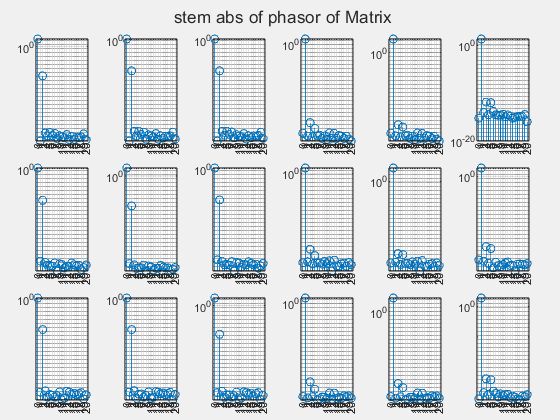


clear G G11 G12 G1 G2 AHm AHp AHpJ AJHm ATB AtHp AtJHm P2T PT QT YT BHm BHp BHpJ BJHm BTB NT XP RT XT P2Hm P2Hp P2HpJ P2JHm PHm PHp PHpJ PJHm

figure(5)
% plot(K1)
% hold on
plot(K2,title="K(t)")

figure(6)
stem(K2)

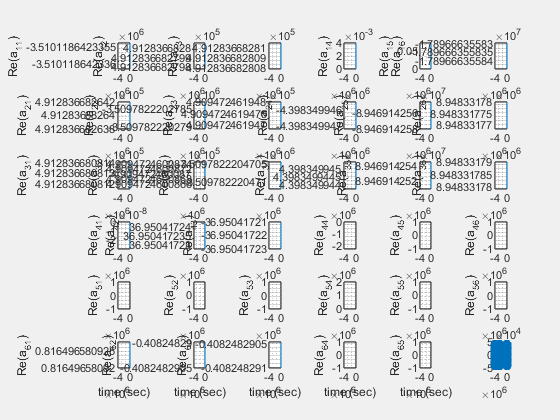


%boucle fermée
% ABF=Atilde-Btilde*K1;
ABF = Atilde-Btilde*K2;
figure(7)
% plot(ABF)
% hold on
plot(ABF)
figure(8)
% plot(ABF.HmqNEig(20,T),'*')
% hold on
plot(HmqNEig(ABF,20,T),'o')

## Simulation du systeme

%storage for simulation 
clear StoreSimu

StoreSimu.t = 0;
StoreSimu.y = 0;
StoreSimu.x0 = 0;
StoreSimu.Fs = 0;
StoreSimu.fode = 0;
StoreSimu.w_sc = 0;
StoreSimu.Bw = 0;
StoreSimu.K = 0;
StoreSimu.outmes = 0;
StoreSimu.u = 0;
StoreSimu.win = 0;
StoreSimu = StoreSimu([],1)


StoreSimu = 

  0×1 empty struct array with fields:

    t
    y
    x0
    Fs
    fode
    w_sc
    Bw
    K
    outmes
    u
    win



clear StoreSimu_i
polyBase = @(tt) (3*tt.^2+-2*tt.^3).*(tt>0).*(tt<1) + 1.*(tt>=1);
polyBase2 = @(tt) (4*tt.^3+-3*tt.^4).*(tt>0).*(tt<1) + 1.*(tt>=1);

%input
Bw=PhasorArray([zeros(3,3);[1/model.J 0 0];[0 ,-1 0; 0 0 -1]]);
w_target.value = 2500*2*pi/60;
w_target.tIn = 1;
w_target.Dt = .1;
torqueIn0.value = -1;
torqueIn0.tIn = 3;
torqueIn0.Dt = 0.1;

torqueIn1.value = 7/8/10;
torqueIn1.tIn = 3;
torqueIn1.Dt = 0.1;
torqueIn1.dephase = 0.43;




w = @(y,tt) PhasorArray(...
    cat(3,...
    [torqueIn0.value*polyBase2((tt-torqueIn0.tIn)/torqueIn0.Dt); ...
    min(max(0,w_target.value*polyBase2((tt-w_target.tIn)/w_target.Dt)),w_target.value); ...
    0],...
    [polyBase2((tt-torqueIn1.tIn)/torqueIn1.Dt)*exp(1i*torqueIn1.dephase)*y(4)*torqueIn1.value; ...
    0; ...
    0]) ...
,'z_pospart',true);

w_sc = @(y,tt) cat(3, ...
    [-2*imag(polyBase2((tt-torqueIn1.tIn)/torqueIn1.Dt)*exp(1i*torqueIn1.dephase)*y(4)*torqueIn1.value) ...
    ;0;0], ...
    [torqueIn0.value*polyBase2((tt-torqueIn0.tIn)/torqueIn0.Dt); ...
    min(max(0,w_target.value*polyBase2((tt-w_target.tIn)/w_target.Dt)),w_target.value); ...
    0], ...
    [2*real(polyBase2((tt-torqueIn1.tIn)/torqueIn1.Dt)*exp(1i*torqueIn1.dephase)*y(4)*torqueIn1.value) ...
    ;0;0]...
    );

K=K2.trunc(2);
fod = @(t,y) fode(t,y,ABF,model.p,Bw,w);

% ABF=Atilde-Btilde*K;
phase_error=2*pi/100*0;


Atilde=[[A;C.PhaseShift(phase_error)],zeros(size(A,1)+size(C,1),size(C,1))];
Btilde=[B;zeros(size(C,1),size(B,2))];

ABF=Atilde-Btilde*K.PhaseShift(phase_error);

ABFsc = ABF.SinCosForm();
Asc = A.SinCosForm();
Bsc = B.SinCosForm();
Csc = SinCosForm(C.PhaseShift(phase_error));
Ksc = SinCosForm(K.PhaseShift(phase_error));
Bwsc = Bw.SinCosForm();
% w_sc = @(y,tt) w(y,tt).SinCosForm();

fod = @(t,y) fodeCosSin(t,y,ABFsc,model.p,Bwsc,w_sc);
fodd = @(t,y,Z) fodeCosSinWithDelay(t,y,Z,Asc,Bsc,Csc,Ksc,model.p,Bwsc,w_sc);
fodbis = @(t,y) fodeCosSinWithDelay(t,y,[y y],Asc,Bsc,Csc,Ksc,model.p,Bwsc,w_sc);
% fodeCosSinWithDelay(t,y,Z,Asincos,Bsincos,Csincos,Ksincos,p,Bwsincos,wsincos)

delays=[0.001 0.001];

history=[zeros(nx+1,1)];

Fs=40e3;
tspan = [0:1/Fs:8];

x0=[zeros(nx+1,1)];
x0(4)=0*2*pi/60;
full_state=[model.state_name model.int_name 'harmonic Phase'];

dFdy = @(t,y) jacobianCosSin(t,y,ABFsc,model.p);
opts = odeset('Jacobian',dFdy);

t1=tic();

[t,y]=ode15s(fod,tspan,x0,opts);
% [t,y]=ode15s(fod,tspan,x0);
% [t,y]=ode15s(fodbis,tspan,x0);
% [t,y]=ode15s(fodbis,tspan,x0,opts);
% sol = dde23(fodd,delays,history,tspan)

toc(t1)

Elapsed time is 3.376028 seconds.




theta_sim=y(:,end)';

Csct=evalSC(Csc,theta_sim);
z=squeeze(pagemtimes(Csct,permute(y(:,1:4),[2,3,1])));

Csct_real=evalSC(SinCosForm(C),theta_sim);
z_real=squeeze(pagemtimes(Csct_real,permute(y(:,1:4),[2,3,1])));


Ksct=evalSC(Ksc,theta_sim);
u=squeeze(pagemtimes(Ksct,permute(y(:,1:end-1),[2,3,1])));


Win=zeros(3,numel(t));
for ti = 1:numel(t)
    Win(:,ti)=evalSC((w_sc(y(ti,1:4),t(ti))),y(ti,end));
end
 
toc(t1)

Elapsed time is 6.150590 seconds.



StoreSimu_i.t = t;
StoreSimu_i.y = y;
StoreSimu_i.x0 = x0;
StoreSimu_i.Fs = Fs;
StoreSimu_i.fode = fod;
StoreSimu_i.w_sc = w_sc;
StoreSimu_i.Bw = Bw;
StoreSimu_i.K = K;
StoreSimu_i.outmes = z;
StoreSimu_i.u = u;
StoreSimu_i.win = Win;
toc(t1)

Elapsed time is 6.159966 seconds.



StoreSimu(end+1)=StoreSimu_i

StoreSimu = 1×3 struct array with fields:
    t
    y
    x0
    Fs
    fode
    w_sc
    Bw
    K
    outmes
    u
    win



f1=figure;
clf(f1)
T1=tiledlayout(f1,size(Atilde,1)+1,1,"TileSpacing","compact","Padding","compact");

f2=figure;
clf(f2)
T2=tiledlayout(f2,size(C,1),1,"TileSpacing","compact","Padding","compact");

f3=figure;
clf(f3)
T3=tiledlayout(f3,size(K2,1),1,"TileSpacing","compact","Padding","compact");

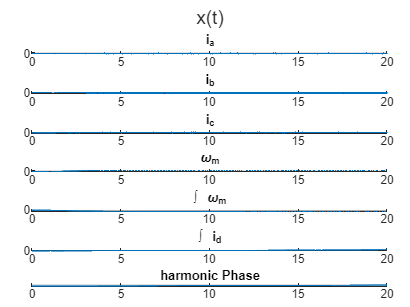


    for ii=1:size(y,2)
        nexttile(T1,ii);
        hold on
        plot(t,y(:,ii))
        grid on
        title(full_state{ii})
    end
    sgtitle('x(t)')
    linkaxes(T1.Children,'x')

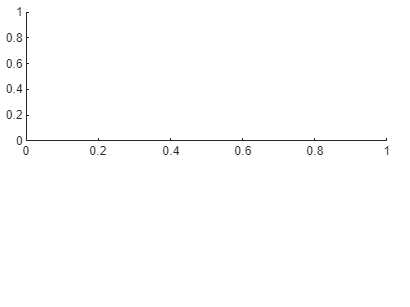

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

    pause(1)

    for ii=1:size(z,1)
        nexttile(T2,ii)
        hold on
        plot(t,z(ii,:))
        plot(t,z_real(ii,:))
        grid on
        title(model.output_name{ii})
    end

    sgtitle('C(t) x')
    linkaxes(T2.Children,'x')
    pause(1)

    for ii=1:size(u,1)
        nexttile(T3,ii)
        hold on
        plot(t,u(ii,:))
        grid on
        %         title(model.output_name{ii})
    end
    sgtitle('Kx')
    pause(1)
    linkaxes(T3.Children,'x')


f4=figure(12);
clf
T4=tiledlayout(f4,size(Win,1),1,"TileSpacing","compact","Padding","compact");

    for ii=1:size(Win,1)
        nexttile(T4,ii)
        hold on
        plot(t,Win(ii,:))
        grid on
        %         title(model.output_name{ii})
    end


theta_hmq = y(:,end);
omeg_mot = y(:,4);
omeg_hmq = model.p*y(:,4);
domeg_mot=gradient(omeg_mot,1/Fs);
domeg_hmq=gradient(omeg_hmq,1/Fs);

figure(13)
clf
T=tiledlayout(4,1);
nexttile   
plot(t,y(:,4))
hold on
plot(t,z(1,:),'r--')
hold off
title('\omega_m(t)')

grid on
nexttile   
plot(t,domeg_hmq)
title('D_t \omega_h(t)')
grid on
nexttile   
plot(t,domeg_hmq./omeg_hmq)
title('D_t( \omega_h(t) )/ \omega_h')
grid on
nexttile   
plot(t,domeg_hmq./omeg_hmq./omeg_hmq)
title('D_t( \omega_h(t) )/ \omega_h^2')
grid on

linkaxes(T.Children,'x')


figure(131)
TT=tiledlayout(3,1);
nexttile
plot(theta_hmq,omeg_mot)
grid minor
title('\omega_m')
nexttile
plot(theta_hmq,omeg_hmq)
grid minor
title('\omega_{elec}')
nexttile
plot(theta_hmq,gradient(omeg_hmq,theta_hmq))    
grid minor
title('d \omega_h / d \theta_h')

xlabel('phase (\theta_{elec})')
linkaxes(TT.Children,'x')
xlim([0 4*pi])


figure(14)
I=find(model.p*y(:,4)>0,1)-1;

angularsft(theta_hmq(I:end),t(I:end),omeg_hmq(I:end), ...
    {y(I:end,1),y(I:end,4),domeg_mot(I:end),domeg_mot(I:end)./y(I:end,4)}, ...
    0:5,{'i_{a}','\omega_m','D_t \omega_m','D_t\omega_m / \omega_m'},...
    [1 1 0 1 1])

ans =   Text with properties:

         String: ''
       FontSize: 13
     FontWeight: 'normal'
       FontName: 'Helvetica'
          Color: [0.1500 0.1500 0.1500]
    Interpreter: 'tex'

  Show all properties


ans = 4×1 cell array
    {6×280019 double}
    {6×280019 double}
    {6×280019 double}
    {6×280019 double}


ans =   Text with properties:

         String: ''
       FontSize: 13
     FontWeight: 'normal'
       FontName: 'Helvetica'
          Color: [0.1500 0.1500 0.1500]
    Interpreter: 'tex'

  Show all properties


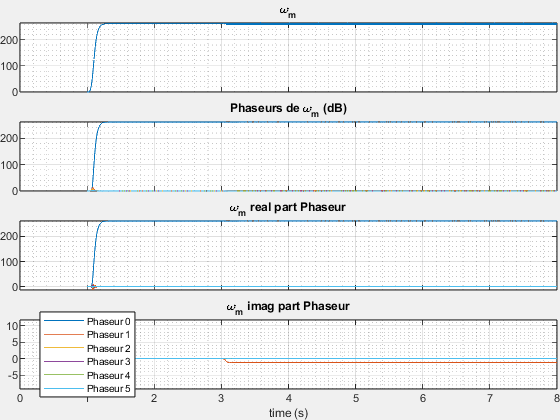

ans = 1×1 cell array
    {6×280019 double}



% figure
% 
% angularsft(y(I:end,end),t(I:end),model.p*y(I:end,4),{y(I:end,1),y(I:end,4),domeg(I:end),domeg(I:end)./y(I:end,4)},0:5,{'i_{a}','\omega_m','D_t \omega_m','D_t\omega_m / \omega_m'},[1 1 0 1 1])

angularsft(y(I:end,end),t(I:end),model.p*y(I:end,4),...
    {y(I:end,4)},0:5,{'\omega_m'},[1 1 0 1 1])

ans =   Text with properties:

         String: ''
       FontSize: 13
     FontWeight: 'normal'
       FontName: 'Helvetica'
          Color: [0.1500 0.1500 0.1500]
    Interpreter: 'tex'

  Show all properties


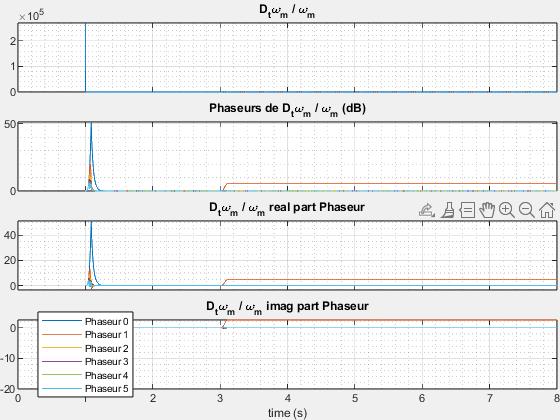

ans = 1×1 cell array
    {6×280019 double}



angularsft(y(I:end,end),t(I:end),model.p*y(I:end,4),...
    {domeg_mot(I:end)./y(I:end,4)},0:5,{'D_t\omega_m / \omega_m'},...
    [1 1 0 1 1])

I=1

I = 1

ans =   Text with properties:

         String: ''
       FontSize: 13
     FontWeight: 'normal'
       FontName: 'Helvetica'
          Color: [0.1500 0.1500 0.1500]
    Interpreter: 'tex'

  Show all properties


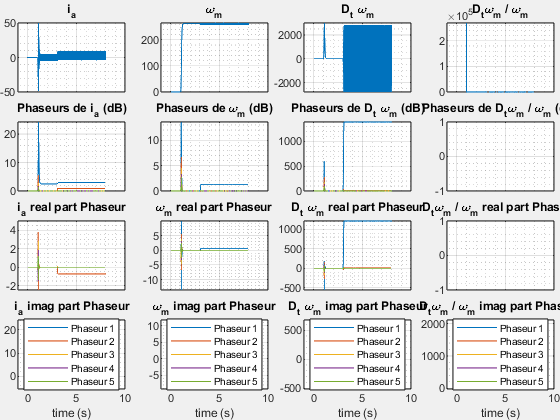

ans = 4×1 cell array
    {5×320001 double}
    {5×320001 double}
    {5×320001 double}
    {5×320001 double}


angularsft(y(I:end,end),t(I:end),model.p*y(I:end,4),...
    {y(I:end,1),y(I:end,4),domeg_mot(I:end),domeg_mot(I:end)./y(I:end,4)},1:5,{'i_{a}','\omega_m','D_t \omega_m','D_t\omega_m / \omega_m'},...
    [1 1 0 1 1])

### Verif de la stab

$\mathcal{A-N(\omega_0)-BK}$ se balade dans un polytope entre les deux vitesse moyennes maximale du moteur. K est indep de $\omega_0$. 

Pour être exact :


$$\mathcal{A-N(\omega_0)-BK} = \mathcal{A-\omega_0 \times N(1)-BK} =  \mathcal{A}_0 + \omega_0  \mathcal{A}_1$$


C'est à dire que la matrice harmonique A dépend de manière affine du parametre, et donc se balade dans un polytope de dim 1. 

Si on trouve une fonction de lyapunov valable sur tout ce polytope, alors on a prouvé la stabilité. 

%
% hP=20
% hlmi=10
% P2=PhasorArray.ndsdpvar(size(ABF,1),size(ABF,1),hP)
% PT=P2.TB(hlmi)
%
% ABFT=ABF.TB(hlmi)
% [AHpJ,AJHm,AHp,AHm]=ABF.TBHankel(hlmi);
% [AtHpJ,AtJHm,AtHp,AtHm]=TBHankel(ABF',hlmi);
% [PHpJ,PJHm,PHp,PHm]=P2.TBHankel(hlmi);
% F=[PT>=0]
%
%
% RPM_bornes=[-5000 5000]
% f_meca_bornes=RPM_bornes/60;
% f_elec_bornes=p*f_meca_bornes;
% T_elec_bornes=1./f_elec_bornes;
%
%
% for T=T_elec_bornes
%     base_lmi=(ABFT-NTB(ABF,hlmi,T))'*PT+PT*(ABFT-NTB(ABF,hlmi,T))
%     cor_lmi=AtHp*PHm+PHp*AHm+AtJHm*PHpJ+PJHm*AHpJ
%     F11=base_lmi+cor_lmi
%     F=[F;F11<=0]
% end
%
% optimize(F)
%
%
% P2=P2.sdpval
% figure
% plot(P2)
% hold on
% plot(PP)
%
% figure
% stem(P2)


## Correcteur gain schedulé

Tran, G. Q. B., Pham, T.-P., Sename, O., Gáspár, P. (2023) "Design of an LMI-based Polytopic LQR Cruise Controller for an Autonomous Vehicle towards Riding Comfort", Periodica Polytechnica Transportation Engineering, 51(1), pp. 1–7. [https://doi.org/10.3311/PPtr.20075](https://doi.org/10.3311/PPtr.20075)

hP=5;
hlmi=10

hlmi = 10


BTB=Btilde.TB(hlmi);
Cz=[PhasorArray(Q^(1/2));zeros(size(R,1),size(Q,2))];
Dz=[zeros(size(Q,1),size(R,2));PhasorArray(R^(1/2))];
Bw=PhasorArray.eye(Atilde.size(1));
BwT=Bw.TB(hlmi);

P3=PhasorArray.ndsdpvar(Atilde.size(1),Atilde.size(1),hP);

ATB=Atilde.spTB(hlmi);
P3T=P3.TB(hlmi);

[AHpJ,AJHm,AHp,AHm]=Atilde.spTBHankel(hlmi);
[AtHpJ,AtJHm,AtHp,AtHm]=spTBHankel(Atilde.',hlmi);

CzT=Cz.spTB(hlmi);
[CzHpJ,CzJHm,CzHp,CzHm]=Cz.spTBHankel(hlmi);
[CztHpJ,CztJHm,CztHp,CztHm]=spTBHankel(Cz.',hlmi);

DzT=Dz.spTB(hlmi);
[DzHpJ,DzJHm,DzHp,DzHm]=Dz.spTBHankel(hlmi);
[DztHpJ,DztJHm,DztHp,DztHm]=spTBHankel(Dz.',hlmi);

[P3HpJ,P3JHm,P3Hp,P3Hm]=P3.spTBHankel(hlmi);

[BHpJ,BJHm,BHp,BHm]=Btilde.spTBHankel(hlmi);

gam = sdpvar;
G=[gam>=0,P3T>=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                            Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|           Element-wise inequality 1x1|              1 to 1|
|   #2|   Matrix inequality (complex) 126x126|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


Nv=1; %number of parameter
clear cY cW YT WT YHpJ YJHm YHp YHm
for ii = 1:2^Nv
    T=T_elec_bornes(ii);
    cY{ii} = PhasorArray.ndsdpvar(Btilde.size(2),Btilde.size(1),hP,"PhasorType",'full');
    cW{ii} = PhasorArray.ndsdpvar(Btilde.size(2)+Atilde.size(1),Btilde.size(2)+Atilde.size(1),hP,"PhasorType",'symmetric') ;
    YT{ii} = cY{ii}.spTB(hlmi);
    WT{ii} = cW{ii}.spTB(hlmi);
    [YHpJ{ii},YJHm{ii},YHp{ii},YHm{ii}]=cY{ii}.spTBHankel(hlmi);

    G11=[(ATB-NTB(Atilde,hlmi,T))*P3T+AHp*P3Hm+AJHm*P3HpJ];
    G12=[BTB*YT{ii}+BHp*YHm{ii}+BJHm*YHpJ{ii}];
    G1=G11+G11'+G12+G12'+BwT*BwT';
    G=[G;G1<=0];

    G2=[P3T,(CzT*P3T+CzHp*P3Hm+CzJHm*P3HpJ+DzT*YT{ii}+DzHp*YHm{ii}+DzJHm*YHpJ{ii})';...
        (CzT*P3T+CzHp*P3Hm+CzJHm*P3HpJ+DzT*YT{ii}+DzHp*YHm{ii}+DzJHm*YHpJ{ii}), WT{ii}];
    G=[G;G2>=0];
    G=[G;trace(WT{ii})<=gam];
end
obj = gam;
G

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                            Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|           Element-wise inequality 1x1|              1 to 1|
|   #2|   Matrix inequality (complex) 126x126|              1 to 1|
|   #3|   Matrix inequality (complex) 126x126|   0.20412 to 800000|
|   #4|   Matrix inequality (complex) 315x315|      1 to 3162.2777|
|   #5|           Element-wise inequality 1x1|             1 to 21|
|   #6|   Matrix inequality (complex) 126x126|   0.20412 to 800000|
|   #7|   Matrix inequality (complex) 315x315|      1 to 3162.2777|
|   #8|           Element-wise inequality 1x1|             1 to 21|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


optimize(G,obj)


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 1618            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 3               
  Matrix variables       : 5               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 0.4799
       solvertime: 22.5891
             info: 'Infeasible problem (<a href="yalmip.github.io/debugginginfeasible">learn to debug</a>) (MOSEK-SDP)'
          problem: 1


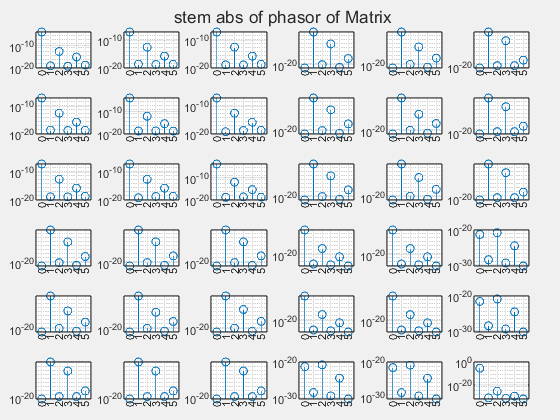

figure(14)
stem(P3)

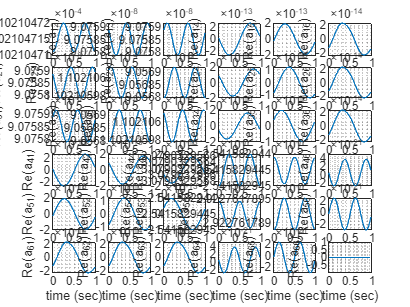

figure(15)
plot(sdpval(P3))

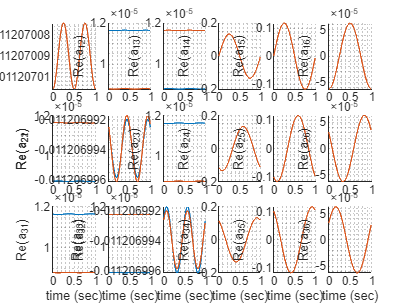


figure(16)
for ii=1:2
    hold on
    cK{ii}=trunc(sdpval(cY{ii})/sdpval(P3),10);
    plot(cK{ii})
end

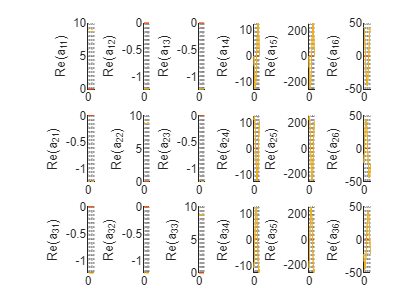

figure(17)
clf

for ii=1:2
    hold on
    plot(-cK{ii},linetype='-.')
end
% hold on
% plot(K1)
hold on
plot(K2)


bound_sch=2*pi./T_elec_bornes;

Bw=PhasorArray([zeros(3,3);[1/model.J 0 0];[0 ,-1 0; 0 0 -1]]);
fod = @(t,y) fode_QLPV(t,y,Atilde,Btilde,model.p,Bw,w,cK{1}.trunc(2),cK{2}.trunc(2),bound_sch);
Fs=20e3;


[t,y]=ode15s(fod,[0:1/Fs:20],[zeros(nx+1,1)]);

for ii=1:size(y,2)
    nexttile(T1,ii);
    hold on
    plot(t,y(:,ii))
    grid on
    title(full_state{ii})
end

Invalid or deleted object.

Error in nexttile

Error in nexttile

sgtitle('x(t)')

Ctime=arrayfun(@(ang) real(evalp(C,ang)),y(:,end),'UniformOutput',false);
Ctime=cat(3,Ctime{:});
z=squeeze(pagemtimes(Ctime,permute(y(:,1:4),[2,3,1])));
for ii=1:size(z,1)
    nexttile(T2,ii)
    hold on
    plot(t,z(ii,:))
    grid on
    title(model.output_name{ii})
end
sgtitle('C(t) x')

alph= @(om) (om-bound_sch(1))/(bound_sch(2)-bound_sch(1))

KK1=value(trunc(cK{1},2));
KK2=value(trunc(cK{2},2));
Ktime=arrayfun(@(om,ang) real(evalp(PhasorArray(KK1*(1-alph(om))+alph(om)*KK2),ang)),y(:,4)*model.p,y(:,end),'UniformOutput',false);
Ktime=cat(3,Ktime{:});
u=squeeze(pagemtimes(Ktime,permute(y(:,1:end-1),[2,3,1])));
for ii=1:size(u,1)
    nexttile(T3,ii)
    hold on
    plot(t,u(ii,:))
    grid on
    %         title(model.output_name{ii})
end
sgtitle('Kx')


figure(18)
XX=angularsft(y(:,end),t,y(:,4)*model.p,y(:,1:4),0:4)
figure(19)
ZZ=angularsft(y(:,end),t,y(:,4)*model.p,z,0:4)
figure(20)
SS=angularsft(y(:,end),t,y(:,4)*model.p,u,-4:4)


SSp=PhasorArray(permute([SS{1}(:,end) SS{2}(:,end) SS{3}(:,end)],[2 3 1]))
figure(21)
plot(SSp)


## Ajout de precompensateur

Pr1=-(C*(1/(A-B*K2{:,1:4}))*B*[1 0;0 1;-1 -1]);
figure(22)
plot(Pr1);
figure(23)
stem(Pr1);
Pr1=Pr1.trunc(50);
Pr0=1/Pr1;
Pr0=Pr0.trunc(5);

S0=Pr0*[2500*2*pi/60;0]
figure(24)
plot([1 0;0 1;-1 -1]*S0);
hold on
plot(SSp);

figure(25)
stem([1 0;0 1;-1 -1]*S0,'explosed',true,'display','both')
figure
stem(SSp,'explosed',true,'display','both')


figure(26)
lsim((A-B*K2{:,1:4}),0:1/5000:0.2,[],1/(50),[],B*[1 0;0 1;-1 -1]*S0,checkreal=true);


figure(27)
plot(Pr0)

Bw2=Bw;
Bw2{1:4,2:3}=B*[1 0;0 1;-1 -1]*Pr0;
N=[1 0;0 1;-1 -1]*Pr0;
figure(28)
plot(Bw)
hold on
plot(Bw2)

F10=figure(29);
T10=tiledlayout(A.size(1)+C.size(1)+1,1);

F11=figure(30);
T11=tiledlayout(C.size(1),1);

F12=figure(31);
T12=tiledlayout(B.size(2),1);
x0=zeros(7,1)


simandplot_static(model,K2,N*0,Bw,w,Fs,10,x0,T10,T11,T12);
simandplot_static(model,K2,N  ,Bw,w,Fs,10,x0,T10,T11,T12);


P=sqrt(2/3)*[d(bemfm_abc)';bemfm_abc'; [1 1 1]*sqrt(2)/2] %abc vers dq0
PP=[P{1:2,:} [0 ;0];0 0 0 1]
Pdq=P{1:2,:};

Pinv=trunc(1/P,1)
Pinv.Value

PPinv=[Pinv{:,1:2} [0;0;0];[0 0] 1]
figure(32)
plot(Pinv)


K_x=trunc(K2{:,1:4},5)
K2_z=trunc(K2{:,5:6},5)

figure(33)
plot(Pdq*K_x*PPinv)
hold on
plot(trunc(Pdq*K_x*PPinv,0))

figure(60)
clf
plot(Pdq*K2_z)


KK=cK{1};


K_x=trunc(KK{:,1:4},5)
K_z=trunc(KK{:,5:6},5)

figure(34)
plot(Pdq*K_x*PPinv)
hold on
plot(trunc(Pdq*K_x*PPinv,0))

figure(60)
hold on
plot(trunc(Pdq*K_z,1))

KK=cK{2};


K_x=trunc(KK{:,1:4},5)
K_z=trunc(KK{:,5:6},5)

figure(25)
plot(Pdq*K_x*PPinv)
hold on
plot(trunc(Pdq*K_x*PPinv,0))

figure(60)
hold on
plot(trunc(Pdq*K_z,1))


function [t,y,z,s] = simandplot_static(model,K,N,Bw,w,Fs,tmax,x0,T1,T2,T3)
    
    Atilde=[[model.A;model.C],zeros(size(model.A,1)+size(model.C,1),size(model.C,1))];
    Btilde=[model.B;zeros(size(model.C,1),size(model.B,2))];
    full_state=[model.state_name model.int_name 'harmonic Phase'];
    
    Bw{1:4,2:3}=model.B*N;

    ABF=Atilde-Btilde*K;
    fod = @(t,y) fode(t,y,ABF,model.p,Bw,w);
    [t,y]=ode15s(fod,[0:1/Fs:tmax],x0);

    for ii=1:size(y,2)
        nexttile(T1,ii);
        hold on
        plot(t,y(:,ii))
        grid on
        title(full_state{ii})
    end
    sgtitle('x(t)')

    Ctime=arrayfun(@(ang) real(evalp(model.C,ang)),y(:,end),'UniformOutput',false);
    Ctime=cat(3,Ctime{:});
    z=squeeze(pagemtimes(Ctime,permute(y(:,1:4),[2,3,1])));
    for ii=1:size(z,1)
        nexttile(T2,ii)
        hold on
        plot(t,z(ii,:))
        grid on
        title(model.output_name{ii})
    end
    sgtitle('C(t) x')

    Ktime=arrayfun(@(ang) real(evalp(K,ang)),y(:,end),'UniformOutput',false);
    Ktime=cat(3,Ktime{:});
    sk=squeeze(pagemtimes(Ktime,permute(y(:,1:end-1),[2,3,1])));
    Nrtime=arrayfun(@(ang) real(evalp(N,ang)),y(:,end),'UniformOutput',false);
    Nrtime=cat(3,Nrtime{:});
    rtime=arrayfun(@(y,t) evalp(w(y,t),y),y(:,end),t,'UniformOutput',false);
    rtime=cat(3,rtime{:});
    sr=squeeze(pagemtimes(Nrtime,rtime(2:3,1,:)));
    s=sk+sr;
    for ii=1:size(s,1)
        nexttile(T3,ii)
        hold on
        plot(t,s(ii,:))
        grid on
        %         title(model.output_name{ii})
    end
    sgtitle('Kx')
end

function dy =fode(t,y,A,p,Bw,w)


dy=(evalp(A,y(end),"forceReal",true))*y(1:end-1)+(evalp(Bw,y(end),"forceReal",true))*(evalp(w(y,t),y(end),"forceReal",true));%-[0;0;0;0;200]-[0;0;0;50/0.05;0]*(t>0.5);
dy(end+1)=p*y(4); %On integre la fréquence electrique = p * w_meca, pour obtenir l'angle electrique
if ~iscolumn(dy)
    dy=dy';
end
end

function dy =fodeCosSin(t,y,Asincos,p,Bwsincos,wsincos)
winsincos = wsincos(y,t);
hA=(size(Asincos,3)-1)/2;
hB=(size(Bwsincos,3)-1)/2;
hw=(size(winsincos,3)-1)/2;

h=max([hA,hB,hw]);

theta= y(end);
eit = [sin((h:-1:1)'*theta);cos((0:h)'*theta)];


At=tensorprod(Asincos,double(eit((1:(2*hA+1))+h-hA)),3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))
Bt=tensorprod(Bwsincos,double(eit((1:(2*hB+1))+h-hB)),3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))
wt=tensorprod(winsincos,double(eit((1:(2*hw+1))+h-hw)),3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))

dy = At*y(1:end-1) + Bt*wt;
% dy=(evalp(A,y(end),"forceReal",true))*y(1:end-1)+(evalp(Bw,y(end),"forceReal",true))*(evalp(w(y,t),y(end),"forceReal",true));%-[0;0;0;0;200]-[0;0;0;50/0.05;0]*(t>0.5);
dy(end+1)=p*y(4); %On integre la fréquence electrique = p * w_meca, pour obtenir l'angle electrique
if ~iscolumn(dy)
    dy=dy';
end
end


function dy =fodeCosSinWithDelay(t,y,Z,Asincos,Bsincos,Csincos,Ksincos,p,Bwsincos,wsincos)
winsincos = wsincos(y,t);

hA  = (size(Asincos,3)-1)/2;
hB  = (size(Bsincos,3)-1)/2;
hC  = (size(Csincos,3)-1)/2;
hK  = (size(Ksincos,3)-1)/2;
hBw = (size(Bwsincos,3)-1)/2;
hw  = (size(winsincos,3)-1)/2;

h=max([hA,hBw,hw,hB,hK,hC]);

theta_reel= y(end);
eit_real = [sin((h:-1:1)'*theta_reel);cos((0:h)'*theta_reel)];

theta_delay= Z(end,2);
eit_delay = [sin((h:-1:1)'*theta_delay);cos((0:h)'*theta_delay)];


At  = tensorprod(Asincos   ,double(eit_real((1:(2*hA+1))+h-hA))   ,3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))
Bwt = tensorprod(Bwsincos  ,double(eit_real((1:(2*hBw+1))+h-hBw)) ,3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))
Bt  = tensorprod(Bsincos  ,double(eit_real((1:(2*hB+1))+h-hB))  ,3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))
wt  = tensorprod(winsincos ,double(eit_real((1:(2*hw+1))+h-hw))   ,3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))

Kt  = tensorprod(Ksincos   ,double(eit_delay((1:(2*hK+1))+h-hK))   ,3,1);
Ct  = tensorprod(Csincos   ,double(eit_delay((1:(2*hC+1))+h-hC))   ,3,1);

nx = size(At,1);
nc = size(Ct,1);
% nu = size(Bt,1);

dy = [At;zeros(nc,nx)]*y(1:nx) + [Bt*Kt;[Ct , zeros(nc)]]*Z(1:nx+nc,1)+ Bwt*wt;
% dy=(evalp(A,y(end),"forceReal",true))*y(1:end-1)+(evalp(Bw,y(end),"forceReal",true))*(evalp(w(y,t),y(end),"forceReal",true));%-[0;0;0;0;200]-[0;0;0;50/0.05;0]*(t>0.5);
dy(end+1)=p*y(4); %On integre la fréquence electrique = p * w_meca, pour obtenir l'angle electrique

if ~iscolumn(dy)
    dy=dy';
end
end

function J = jacobianCosSin(t,y,Asincos,p)

h  = (size(Asincos,3)-1)/2;

theta_reel= y(end);
eit_real = [sin((h:-1:1)'*theta_reel);cos((0:h)'*theta_reel)];

At  = tensorprod(Asincos   ,double(eit_real)   ,3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))

%d/dtheta A(theta)*y
% si A(theta) = sum a_sk sin(k th) + a_ck cos(kth)
% alors d/dth A(th) = sum  k a_sk cos(k th) - k a_ck sin(kth)
% donc on flip et on multiplie par -k:k;
AsincosDer=flip(Asincos,3);
K=permute((-h):(h),[1 3 2]);
AsincosDer=bsxfun(@times,AsincosDer,K);


AtDth  = tensorprod(AsincosDer ,double(eit_real)   ,3,1); %est un 3D array dont Mt(:,:,k) est M(t(k))
AtDth=AtDth*y(1:end-1);

J = [At AtDth;
    zeros(1, numel(y))];

J(end,4)=p;

end



function dy =fode_QLPV(t,y,A,B,p,Bw,w,K1,K2,bound_sch)
At=real(evalp(A,y(end)));
Bwt=real(evalp(Bw,y(end)));
Bt=real(evalp(B,y(end)));
wt= real(evalp(w(y,t),y(end)));

scheduling_var=p*wt(2);
scheduling_var=p*y(4);
alpha=max(-1,min(1,(+scheduling_var-bound_sch(1))/(bound_sch(2)-bound_sch(1))));

K=alpha*K2.value+(1-alpha)*K1.value;

Kt=real(evalp(PhasorArray(K),y(end)));
dy=(At+Bt*Kt)*y(1:end-1)+Bwt*wt;

% dy=real(evalp(A,y(end)))*y(1:end-1)+real(evalp(Bw,y(end)))*real(evalp(w(y,t),y(end)));%-[0;0;0;0;200]-[0;0;0;50/0.05;0]*(t>0.5);
dy(end+1)=p*y(4); %On integre la fréquence electrique = p * w_meca, pour obtenir l'angle electrique
if ~iscolumn(dy)
    dy=dy';
end
end

function Atheta  =  evalSC(ASC,theta)

h  = (size(ASC,3)-1)/2;
eit_real = [sin((h:-1:1)'*theta);cos((0:h)'*theta)];

Atheta  = tensorprod(ASC ,double(eit_real)   ,3,1);
end


